# Sistemas de segundo orden

Dos polos y ecuaciones diferenciales ordinarias de segundo orden

Ejemplo típico.

Masa Resorte Amortiguador

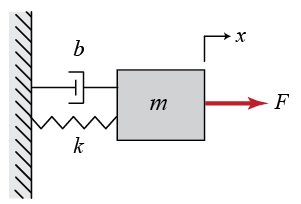

Después de realizar el modelado dinámico del sistema obtenemos la función de transferencia


$$\frac{U(s)}{F(s)}=\frac{1}{ms^2+bs+k}$$


Para analizar fácilmente la función, podemos obtener su forma canónica


$$\frac{U(s)}{F(s)}=\frac{1/m}{s^2+\frac{b}{m}s+\frac{k}{m}} =K\frac{\omega_n^2}{s^2+2\zeta\omega_ns+\omega_n^2}$$


Despejando


$$\omega_n=\sqrt{\frac{k}{m}}$$



$$\zeta=\frac{b}{2\sqrt{km}}$$


$K=\frac{1}{k}$.

El comportamiento dinámico se determina entonces por $\omega_n $ y $\zeta$ de acuerdo a los siguientes valores.

- $\zeta =0$ Sistema oscilatorio

-  $0<\zeta<1$Sistema Subamortiguado

- $\zeta=1
$Sistema críticamente amortiguado

- $\zeta > 1$Sistema sobre amortiguado

Por ejemplo

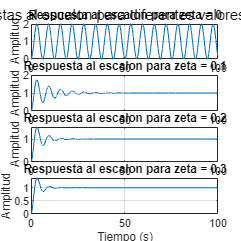

% Parámetros del sistema de segundo orden
omega_n = 1;   % Frecuencia natural (ajusta este valor según tus necesidades)
zeta = [0, 0.1, 0.2, 0.3];  % Valores de factor de amortiguamiento (puedes modificar esta lista)

% Definir el tiempo de simulación
t = 0:0.01:100;  % Vector de tiempo de 0 a 10 segundos con paso de 0.01 segundos

% Inicializar la figura para la representación gráfica
figure;

% Iterar a través de diferentes valores de zeta
for i = 1:length(zeta)
    % Calcular las respuestas del sistema de segundo orden
    num = omega_n^2;
    den = [1, 2*zeta(i)*omega_n, omega_n^2];
    sys = tf(num, den);  % Crear la función de transferencia
    
    % Calcular la respuesta al impulso del sistema
    y = step(sys, t);
    
    % Graficar la respuesta al impulso
    subplot(length(zeta), 1, i);
    plot(t, y);
    title(['Respuesta al escalon para zeta = ', num2str(zeta(i))]);
    xlabel('Tiempo (s)');
    ylabel('Amplitud');
    grid on;
end

% Ajustar el tamaño de la figura para una mejor visualización
fig = gcf;
fig.Position(3) = 800;
fig.Position(4) = 800;

% Ajustar las propiedades de la figura para facilitar la visualización
sgtitle('Respuestas al escalon para diferentes valores de zeta');

% Mostrar la cuadrícula de gráficos
grid on;

Para obtener sus polos

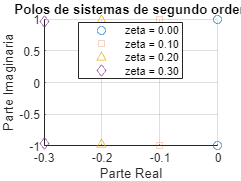


% Inicializar una figura para los polos
figure;
hold on;

% Marcadores (formas) diferentes para los polos
marcadores = {'o', 's', '^', 'd'};

% Iterar a través de diferentes valores de zeta
for i = 1:length(zeta)
    % Calcular los polos del sistema de segundo orden
    num = omega_n^2;
    den = [1, 2*zeta(i)*omega_n, omega_n^2];
    sys = tf(num, den);  % Crear la función de transferencia
    p = pole(sys);  % Calcular los polos
    
    % Graficar los polos en el plano complejo con marcadores diferentes
    plot(real(p), imag(p), marcadores{i}, 'DisplayName', sprintf('zeta = %.2f', zeta(i)));
end

title('Polos de sistemas de segundo orden');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

% Agregar la leyenda
legend('Location', 'Best');

Si queremos obtener los polos en su forma simbolica

% Definir los símbolos y la ecuación simbólica del sistema
syms s omega_n zeta K

% Ecuación simbólica de un sistema de segundo orden
H = K * (omega_n^2 / (s^2 + 2*zeta*omega_n*s + omega_n^2))

$$H = \frac{K\,{\omega_{n}}^{2}}{{\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}}$$

denom=(s^2 + 2*zeta*omega_n*s + omega_n^2)

$$denom = {\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}$$


% Calcular los polos de la ecuación simbólica
polos = solve(denom == 0, s)

$$polos = \left(\begin{array}{c} \omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}-\omega_{n}\,\zeta \\ -\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}-\omega_{n}\,\zeta \end{array}\right)$$


% Mostrar la expresión simbólica de los polos
disp('Expresión simbólica de los polos:');

Expresión simbólica de los polos:


pretty(polos);

/  omega_n sqrt((zeta - 1) (zeta + 1)) - omega_n zeta  \
|                                                      |
\ - omega_n sqrt((zeta - 1) (zeta + 1)) - omega_n zeta /



Para un factor de amortiguamiento igual a 0

zeta=0.5

zeta = 0.5000

polos1=eval(polos)

$$polos1 = \left(\begin{array}{c} -\frac{\omega_{n}}{2}+\frac{\sqrt{3}\,\omega_{n}\,\mathrm{i}}{2}\\ -\frac{\omega_{n}}{2}-\frac{\sqrt{3}\,\omega_{n}\,\mathrm{i}}{2} \end{array}\right)$$

Para un sistema subamortiguado Definimos la frecuencia natural amortiguada


$$\omega_d=\omega_n\sqrt{1-\zeta^{2}}$$


zeta=0.5

zeta = 0.5000

omega_n=1

omega_n = 1

polos2=eval(polos)

polos2 =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


zeta=0.9

zeta = 0.9000

omega_n=1

omega_n = 1

polos3=eval(polos)

polos3 =   -0.9000 + 0.4359i
  -0.9000 - 0.4359i


zeta=0.5

zeta = 0.5000

omega_n=5

omega_n = 5

polos4=eval(polos)

polos4 =   -2.5000 + 4.3301i
  -2.5000 - 4.3301i


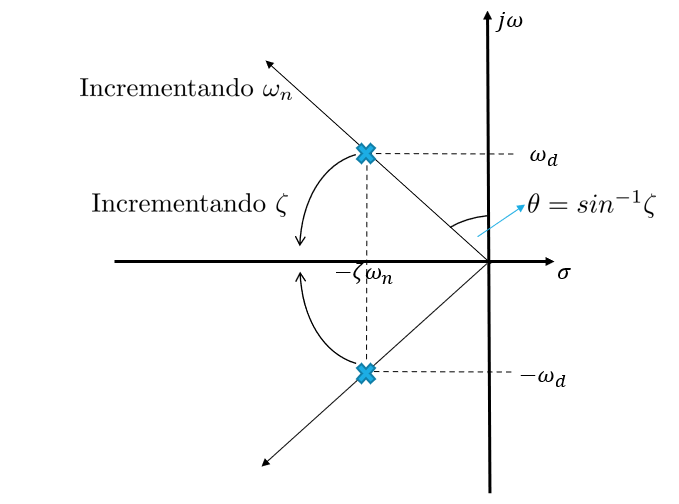

Sistema criticamente amortiguado

zeta=1

zeta = 1

omega_n=1

omega_n = 1

polos5=eval(polos)

polos5 =     -1
    -1


Sistema sobreamortiguado

zeta=1.5

zeta = 1.5000

omega_n=5

omega_n = 5

polos4=eval(polos)

polos4 =    -1.9098
  -13.0902
